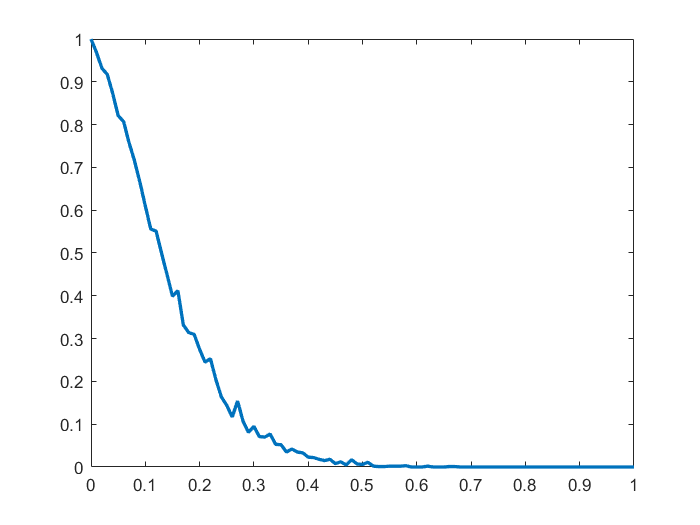

clearvars;
load Hmatrix3.mat
h=H;
row=height(h);
colm=length(h);
transmitted=zeros(1,length(h));
p=0:0.01:1;
Nsim=1000;
nsuc=zeros(1,length(p));

for yy=1:length(p)
    
    for z=1:Nsim
         
        noise=rand(1,colm)<p(yy);
        Msg_received=rem(transmitted+noise,2); % Message Generating              
        for a=1:100 % Iteration loop
            no_0=rem(Msg_received+1,2); %Storing its own voting for bit 0
            no_1=Msg_received; %Storing its own voting for bit 1
            temp=Msg_received; % Temporary variable for storing message before iteration 
            
            for i=1:row
                for j=1:colm
                    if(h(i,j)==1)
                        s=0;
                        for k=1:colm
                            if(h(i,k)==1 && k~=j)
                                s=s+Msg_received(k);
                            end
                        end
                        
                        s=rem(s,2);
                        if(s==1)
                            no_1(j)=no_1(j)+1;
                        else
                            no_0(j)=no_0(j)+1;
                        end
                    end
                end
            end 
            
            for l=1:j     % Majority Voting
                if(no_1(l)>no_0(l)) 
                    Msg_received(l)=1;
                elseif(no_0(l)>=no_1(l))
                    Msg_received(l)=0;
                end             
            end
            
            if(sum(Msg_received)==0) % If Message is successfully decoded
                nsuc(yy)=nsuc(yy)+1;
                break;
            end
            if(temp==Msg_received) %If Messsage is not changed after iteration
                 break;
            end
        end
    end
end

pp=nsuc/Nsim;
plot(p,pp,'LineWidth',2);